# Progetto Segnali ECG

clc;
clear all;

load segnale018.mat %carico il segnale
figure;
segnale = data.segnale;
tempo = data.time;

## Andiamo a visualizzare il segnale da analizzare

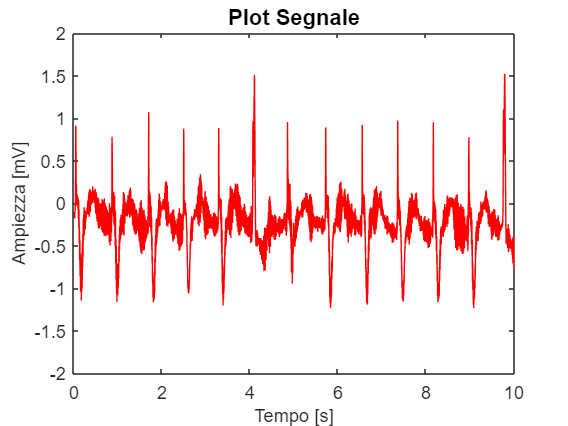

plot(tempo,segnale,'Color','r'); %mostro il segnale non filtrato
xlim([0 10])
ylim([-2 2])
xlabel('Tempo [s]','FontSize',10)
ylabel('Ampiezza [mV]','FontSize',10)
title('Plot Segnale','FontSize',12)

figure;

## FFT per visualizzare lo spettro del segnale

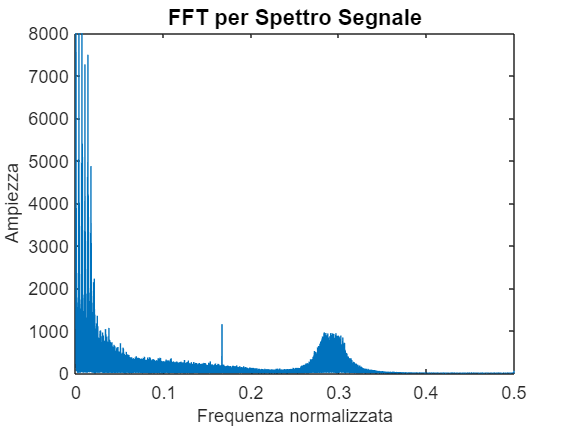

f=(0:length(segnale)-1)/length(segnale); %vettore frequenze normalizzate
plot(f,abs(fft(segnale)))
xlim([0,0.5])%la risposta impulsiva é simmetrica quindi me la limito
ylim([0 8000])
xlabel('Frequenza normalizzata','FontSize',10)
ylabel('Ampiezza','FontSize',10)
title('FFT per Spettro Segnale','FontSize', 12)

## **Filtro con Frequenza Scelta guardando il grafico**

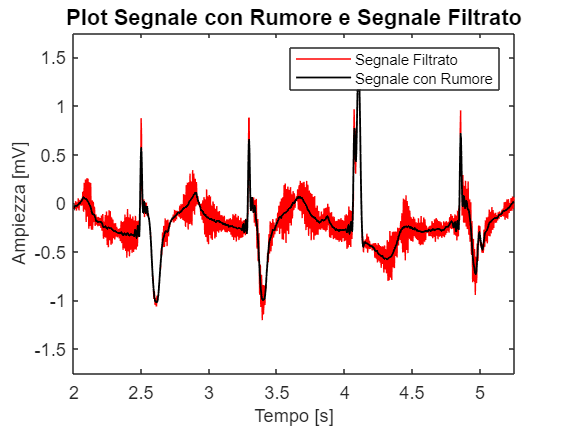

M = 20; %numero di vincoli di progettazione
N = 20; %lunghezza componente causale del filtro
u = linspace(0,0.5,M)'; %genero un vettore frequenze normalizzate
H = (u<0.15); %vettore logico che restituisce 1 quando u<0.15
u = repmat(u,1,N-1); %replico la matrice, con repmat sto replicando u volte, una volta per le righe e N-1 per le colonne. -> Costruisco una matrice a colonne fisse 
                     % in cui a ogni riga corrisponde una frequenza di vincolo.
n = 1:N-1;
n = repmat(n,M,1); %replico la matrice con repmat sto replicando n, M volte per le righe e una volta per le colonne. Sono andata a ripetere 20 volte la riga. 
                   % Costruisco una matrice a righe fisse in cui a ogni colonna 
                   % corrisponde un campione della risposta impulsiva
C = [ones(M,1) 2*cos(2*pi*u.*n)]; %costruisco la matrice C
h = C\H; %calcolo di h = C^{-1} H
h = [h(end:-1:2); h];

figure;
plot(tempo,segnale,'r','LineWidth',0.5)
hold on
plot(tempo,conv(segnale,h,"same"),'black','LineWidth',1)
ylim([-1.75 1.75])
xlim([2 5.25])
xlabel('Tempo [s]','FontSize',10)
ylabel('Ampiezza [mV]','FontSize',10)
legend('Segnale Filtrato','Segnale con Rumore','FontSize',8)
title('Plot Segnale con Rumore e Segnale Filtrato','FontSize',12)
hold off

## Ottimizzazione frequenza di taglio PASSA BASSO

SignalPower = @(x) norm(x(:)-mean(x(:)))^2/length(x(:));
fcut = 0.030:0.001:0.50; %vado a provare tutte le frequenze di taglio da 0.030 a 0.50
for i=(1:length(fcut))
    M = 80; %numero di vincoli
    N = 80; %numero di gradi di libertá
    u = linspace(0,0.5,M)';
    H = (u < fcut(i));
    u = repmat(u,1,N-1);
    n = 1:N-1;
    n = repmat(n,M,1);
    C = [ones(M,1) 2*cos(2*pi*u.*n)];
    h = (C'*C)\C.'*H;
    h = [h(end:-1:2); h];
    segnaleF = conv(segnale,h, 'same');
    segmento_segnale = segnaleF((tempo > 4.05)&(tempo < 4.13));
    segmento_rumore = segnaleF((tempo > 4.50) & (tempo< 4.60));
    SNR(i) = 20*log10(SignalPower(segmento_segnale)/SignalPower(segmento_rumore));
    w(i) = f(i);

end
[SNR_OPT, w_OPT] = max(SNR);
fcut_opt = fcut(w_OPT);
disp(['Frequenza Ottimizzata =' num2str(fcut_opt)]); %converto numero to characters array

Frequenza Ottimizzata =0.146


disp(['Releted SNR =' num2str(SNR_OPT)]); 

Releted SNR =67.5247


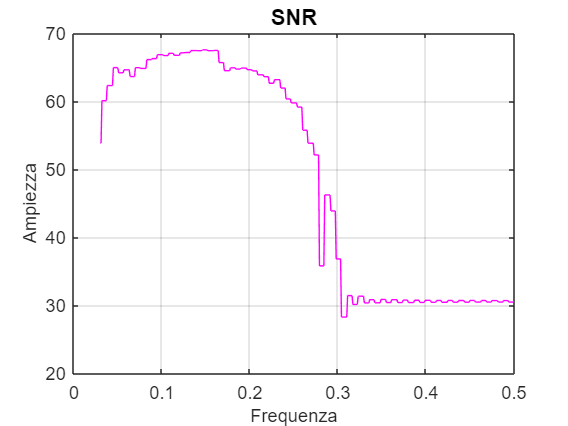

figure;
plot(fcut,SNR,'Color','m')
title('SNR','FontSize',12)
xlabel('Frequenza','FontSize',10)
ylabel('Ampiezza','FontSize',10)
grid on

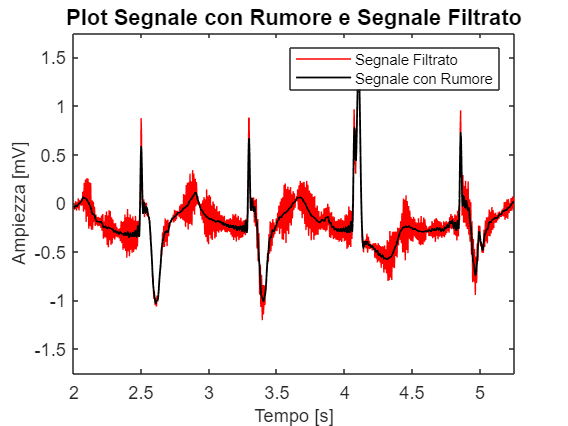


%Applico il filtro con la frequenza di taglio ottimale
M = 80; %numero di vincoli di progettazione
N = 80; %lunghezza componenete causale del filtro
u = linspace(0,0.5,M)'; 
H = (u<fcut_opt); %vettore logico in cui i primi due elementi hanno valore 1 e gli altri hanno valore 0. é un PASSA BASSO.
u = repmat(u,1,N-1); %replico la matrice, con repmat sto replicando u volte, una volta per le righe e N-1 per le colonne.
n = 1:N-1;
n = repmat(n,M,1); %replico la matrice con repmat sto replicando n, M volte per le righe e una volta per le colonne. Sono andata a ripetere 20 volte la riga.
C = [ones(M,1) 2*cos(2*pi*u.*n)];
h = C\H; 
h = [h(end:-1:2); h];

figure;
plot(tempo,segnale,'r','LineWidth',0.3)
hold on
plot(tempo,conv(segnale,h,"same"),'black','LineWidth',1)
ylim([-1.75 1.75])
xlim([2 5.25])
xlabel('Tempo [s]','FontSize',10)
ylabel('Ampiezza [mV]','FontSize',10)
legend('Segnale Filtrato','Segnale con Rumore','FontSize',8)
title('Plot Segnale con Rumore e Segnale Filtrato','FontSize',12)
hold off